syms r theta_0 d theta_temp v t_q1 theta

% 计算弧长距离对极角的函数和极角对时间的导数
r = d/(2*pi)*theta_temp;
f = sqrt(r^2 + diff(r,1,theta_temp));
% L = int(f,theta_temp,0,theta);
L = d/(2*pi)*(0.5*theta*sqrt(1+theta^2)+0.5*log(theta+sqrt(1+theta^2)));
dLdtheta = diff(L,1,theta);
dthetadt = - v/ dLdtheta;

% 获得到中心弧线长度对极角的函数的函数对象从到中心弧线长度对极角的导数对极角的函数的函数对象

L_fun = matlabFunction(L,'Vars',[theta,d]);
dLdtheta_func = matlabFunction(dLdtheta,'Vars', [theta,d]);
% 不同点上间的距离
function dis = getdis(theta_i,theta_j,d)
    r_i = d/(2*pi)*theta_i;
    r_j = d/(2*pi)*theta_j;
    dis = sqrt(r_i^2+r_j^2-2*r_i*r_j*cos(theta_i-theta_j));
end

% 螺线上点从前一个点的极角推后一个点的极角
function theta_iplus1 = solveTheta_onSprail(theta_i, l, d)
    % 定义符号变量
    syms theta_next
    
    % 定义方程
    eqn = theta_i^2 + theta_next^2 - 2*theta_i*theta_next*cos(theta_i - theta_next) == (4*pi^2*l^2)/d^2;
    
    % 设置求解范围
    range = [theta_i,theta_i+pi]; % 解的范围
    
    % 使用 vpasolve 在指定范围内求解方程
    theta_ip1_sol = vpasolve(eqn, theta_next, range);
    
    % 检查是否有解
    if isempty(theta_ip1_sol)
        error('No solution found within the specified range.');
    end
    
    
    theta_iplus1 = double(theta_ip1_sol);
end


% 增加一层封装，
% 接受一个矩阵（纵向为不同情况下的点的极角，
% 横向为不同的点，下标依次增大），返回值为在矩指定的最后一列后再写入一列
function theta_new=getNextPoint(theta,l,d_t,indexOflastPoint)
    theta_last = theta(:,indexOflastPoint);
    theta_new_last = zeros(size(theta_last));
if isscalar(d_t)
    d = ones(size(theta_last)) * d_t;
elseif ismatrix(d_t)
    if size(d_t) == size(theta_last)
        d=d_t;
    else
        disp("d与要迭代的情况个数不一致");
    end
else
    % 错误提示
    disp('不是标量也不是矩阵');
end
    %parfor i = 1:length(theta_last)
    %    theta_new_last(i) = solveTheta(theta_last(i), l, d);
    %end
    %theta_new =[theta, theta_new_last];
        %theta_new_last = zeros(size(theta_last));
    %parfor i = 1:length(theta_last)
    %    theta_new_last(i) = solveTheta(theta_last(i), l, d);
    %end
    theta_new_ = theta;
    n = length(theta_new_last);
    parfor i = 1:n
        theta_new_last(i) = solveTheta_onSprail(theta_last(i), l, d(i));
    end
    theta_new_(:,indexOflastPoint+1) = theta_new_last;
    theta_new =theta_new_;
end
%theta_11 = arrayfun(@(theta) solveTheta(theta, 2.86, 0.55), theta_0_val_q1);
%dis =arrayfun(@(theta1,theta2) getdis(theta1,theta2,0.55),theta_0_val_q1,theta_11);

% 再增加一层封装，
% 接受一个列向量，（纵向为不同时间下的龙头焦点的极角，
% 返回一个矩阵，第一列为输入的列向量，其后为龙头后指定个数个点的极角
function thetaIncludingAfter=solveAfterPoint(theta_0,d,howManyPointsAfterHead,l,l_h)
    [n,~] = size(theta_0);
    thetas = zeros(n ,1+howManyPointsAfterHead);
    %disp(thetas)
    thetas(:,1)=theta_0;
    thetas = getNextPoint(thetas,l_h,d,1);
    for i=2:howManyPointsAfterHead
        thetas = getNextPoint(thetas,l,d, i);

    end
    thetaIncludingAfter = thetas;
end

% 不从龙头开始计算的版本
function thetaIncludingAfter=solveFollowingPoint(theta_0,d,howManyPointsAfterHead,l)
    [n,~] = size(theta_0);
    thetas = zeros(n ,1+howManyPointsAfterHead);
    %disp(thetas)
    thetas(:,1)=theta_0;
    for i=1:howManyPointsAfterHead
        thetas = getNextPoint(thetas,l,d, i);

    end
    thetaIncludingAfter = thetas;
end

% 在不同曲线上点从前一个点的极角推后一个点的极角
function theta_iplus1 = solveTheta_arbitrary(theta_i,l,curve,range)
    % curve 是两个点所在的曲线方程，range是预期的解的范围
    % curve 都是函数对象，传入极角返回极径
    % 定义符号变量
    ri = curve(theta_i);
    % 定义方程
    f =@(theta_next)  ri^2 + curve(theta_next)^2 -2*ri*curve(theta_next)*cos(theta_i-theta_next)-l^2;
    
    % 设置求解范围  待处理 （可能弃用）
    % range = [theta_i,theta_i+pi]; % 解的范围
    
    % 使用 vpasolve 在指定范围内求解方程
    theta_ip1_sol = fzero(f, range);

    % 检查是否有解
    if isempty(theta_ip1_sol)
        error('No solution found within the specified range.');
    end
    
    theta_iplus1 = double(theta_ip1_sol);
end

% 增加一层封装，
% 接受一个矩阵（纵向为不同情况下的点的极角，
% 横向为不同的点，下标依次增大），返回值为在矩指定的最后一列后再写入一列，也就是不同时间下下一个点
% 支持输入曲线方程
function theta_new=getNextPoint_arbitrary(theta,l,indexOflastPoint,curve)
    theta_last = theta(:,indexOflastPoint);
    theta_new_last = zeros(size(theta_last));
    % 仅留档
    %parfor i = 1:length(theta_last) 
    %    theta_new_last(i) = solveTheta(theta_last(i), l, d);
    %end
    %theta_new =[theta, theta_new_last];
        %theta_new_last = zeros(size(theta_last));
    %parfor i = 1:length(theta_last)
    %    theta_new_last(i) = solveTheta(theta_last(i), l, d);
    %end
    theta_new_ = theta;
    n = length(theta_new_last);
 
    for i = 1:n
        range = [theta_last(i),theta_last(i)+pi];
        theta_new_last(i) = solveTheta_arbitrary(theta_last(i), l,curve,range);
    end
    theta_new_(:,indexOflastPoint+1) = theta_new_last;
    theta_new =theta_new_;
end
%theta_11 = arrayfun(@(theta) solveTheta(theta, 2.86, 0.55), theta_0_val_q1);
%dis =arrayfun(@(theta1,theta2) getdis(theta1,theta2,0.55),theta_0_val_q1,theta_11);

% 再增加一层封装，
% 接受一个列向量，（纵向为不同时间下的龙头焦点的极角，
% 返回一个矩阵，第一列为输入的列向量，其后为龙头后指定个数个点的极角
% 支持输入曲线方程
function thetaIncludingAfter=solveAfterPoint_arbitrary(theta_0,howManyPointsAfterHead,l,l_h,curve)
    [n,~] = size(theta_0);
    thetas = zeros(n ,1+howManyPointsAfterHead);
    %disp(thetas)
    thetas(:,1)=theta_0;
    thetas = getNextPoint_arbitrary(thetas,l_h,1, curve);
    for i=2:howManyPointsAfterHead
        thetas = getNextPoint_arbitrary(thetas,l, i, curve);

    end
    thetaIncludingAfter = thetas;
end

 % solveAfterPoint(theta_0_val_q1,0.55,223,1.65,2.86)
 % solveAfterPoint(theta_0_val_q1(1:3),0.55,20,1.65,2.86)
 % solveAfterPoint(thetas_sries,0.55,223,l,l_h)

% 相邻点的极角，后者对前者的导数
syms theta_i theta_ip1 l d
F = theta_i^2 + theta_ip1^2 - 2*theta_i*theta_ip1*cos(theta_i - theta_ip1) - (4*pi^2*l^2)/d^2;
dFdtheta_i = diff(F,theta_i);
dFdtheta_ip1 = diff(F,theta_ip1);
dtheta_ip1dtheta_i = - dFdtheta_i/dFdtheta_ip1;
dtheta_ip1dtheta_i_func=matlabFunction(dtheta_ip1dtheta_i, 'Vars', [theta_i,theta_ip1]);


l_h = 2.86;
l = 1.65;
% 第一问
% 积分得时间对龙头极角的函数符号对象
syms theta_0_start
d_q1=0.55;
v_q1=1.00;
dthetadt_sprial = subs(dthetadt,theta,theta_0);
t_theta_0_q1_ =int(1/dthetadt_sprial,theta_0);
t_theta_0_q1 = t_theta_0_q1_ - subs(t_theta_0_q1_,theta_0,theta_0_start);




% 求不同时间下龙头极角的值（数值解）
% 定义微分方程
dthetadt_val_q1 = subs(dthetadt_sprial,[d,v],[d_q1,v_q1]);
dthetadt_func_q1 = matlabFunction(dthetadt_val_q1, 'Vars', theta_0);

% 设置初始条件和时间范围
theta0_q1 = 32*pi; % 初始条件
tspan_q1 = 0:1:300; % 时间范围从 0 到 300

% 调用 ode45 求解
opts = odeset('RelTol',1e-20,'AbsTol',1e-20);
[t_q1, theta_0_val_q1] = ode45(@(t, theta_temp) dthetadt_func_q1(theta_temp), tspan_q1, theta0_q1,opts);

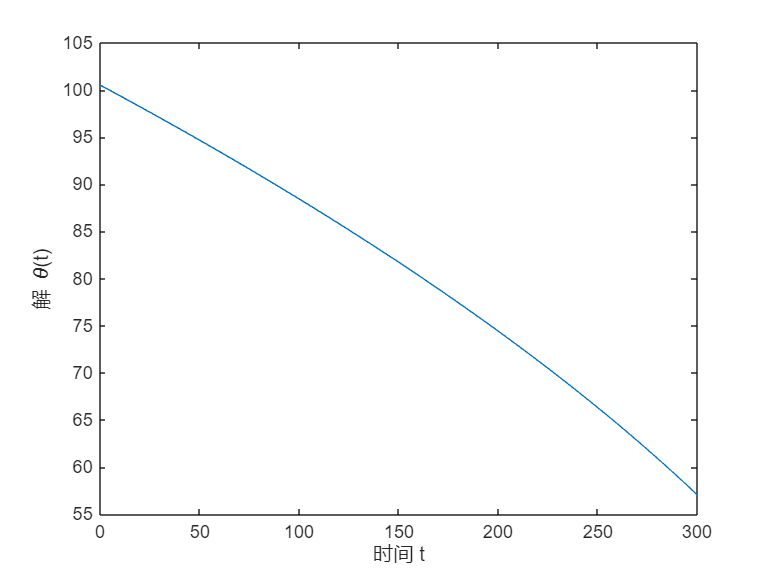

% [t, theta_0_val] = ode45(@(t, theta) dthetadt_func(theta), tspan, theta0);
% 绘制结果
plot(t_q1, theta_0_val_q1);
xlabel('时间 t');
ylabel('解 \theta(t)');

% 将时间对龙头极角的函数的数值对象带入第一问的参数并转化为函数对象
t_theta_0_val_q1 = subs(t_theta_0_q1,[d,v],[d_q1,v_q1]);
t_theta_0_func_q1 = subs(t_theta_0_val_q1,theta_0_start,32*pi);
t_theta_0_func_q1 =  matlabFunction(t_theta_0_func_q1, 'Vars', theta_0);

% 累计误差
error_q1=sqrt(sum((t_q1-t_theta_0_func_q1(theta_0_val_q1)).^2)/301)

error_q1 = 1.2102e-10

% thetas_val_q1  = theta_0_val_q1
%thetas_val_q1 = addNextPoint(thetas_val_q1,l_h,d_q1)
% 计算不同时刻下龙头后各点的极角
[n,~]= size(theta_0_val_q1);
thetas_val_q1_all = zeros(n ,224);
thetas_val_q1_all(:,1)=theta_0_val_q1;
thetas_val_q1_all = getNextPoint(thetas_val_q1_all,l_h,d_q1,1);
for i=2:224
    thetas_val_q1_all = getNextPoint(thetas_val_q1_all,l,d_q1, i);
end
thetas_val_q1 = thetas_val_q1_all(:,2:end);

%%thetas_val_q1_all_test = solveAfterPoint(theta_0_val_q1(1:3),d_q1, 20,1.65,2.86)

% 点的距离检查
dis =zeros(n,223);
parfor i=1:223
    for j=1:n
        dis(j,i)= getdis_a(thetas_val_q1_all(j,i),thetas_val_q1_all(j,i+1),d_q1);
    end
end

% 计算速度
dtheta_idtheta_ip1_val = zeros(n,223);
parfor i = 1:223
    for j = 1:n
        dtheta_idtheta_ip1_val(j,i) = dtheta_ip1dtheta_i_func(thetas_val_q1_all(j,i),thetas_val_q1_all(j,i+1));
    end
end
dtheta_idtheta_ip1_val_multiplicative = dtheta_idtheta_ip1_val;
for i = 2:223
    for j = 1:n
        dtheta_idtheta_ip1_val_multiplicative(j,i) = dtheta_idtheta_ip1_val_multiplicative(j,i)*dtheta_idtheta_ip1_val_multiplicative(j,i-1);
    end
end

% 计算速度
vs = zeros(size(thetas_val_q1));
parfor i = 1:223
    for j = 1:n
        vs(j,i)=dLdtheta_func(thetas_val_q1(j,i), d_q1)*dtheta_idtheta_ip1_val_multiplicative(j,i)*dthetadt_func_q1(theta_0_val_q1(j));
    end
end

vshow = -vs

rho = d_q1/(2*pi)*thetas_val_q1_all
% 创建一个新的图形窗口
figure;

% 遍历每一行并绘制极坐标散点图
c =ones(1,224)*3
c(1)=2
for i = 1:size(thetas_val_q1_all, 1)
    polarscatter(0, max(rho),5);
    polarscatter(thetas_val_q1_all(i, :), rho(i, :),25,c,'filled');
    pause(0.05);

end


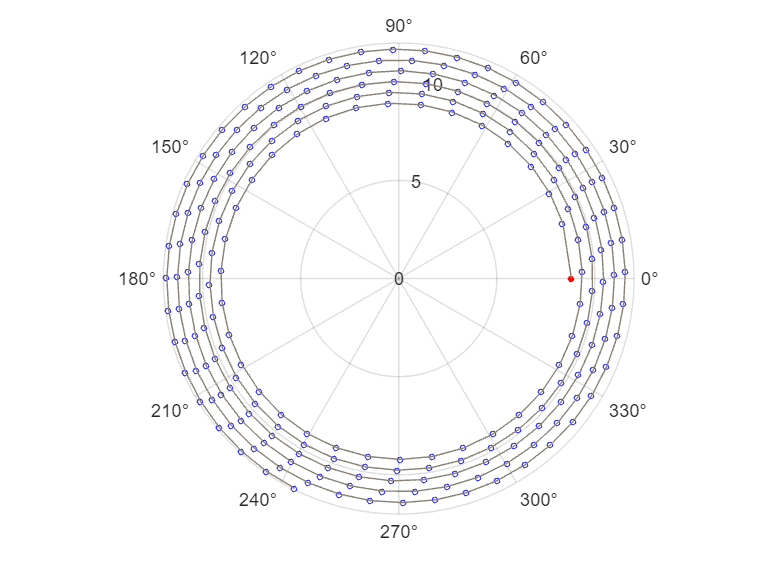

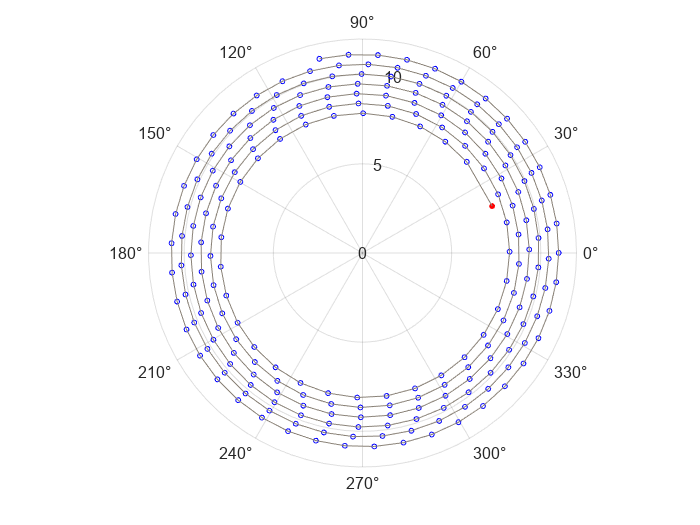

% 动图
drow(thetas_val_q1_all,@(t_n) d_q1/2/pi*t_n,@(t_n) t_n);

% 第二问
%check=crossfunctions(theta_0_val_q1(301), thetas_val_q1(301,:), d_q1*theta_0_val_q1(301)/2/pi, d_q1*thetas_val_q1(301,:)/2/pi, 222, 2.86, 1.65)
%max(check)
maxs = zeros(300,1);
all_ = zeros(300,4);

% 绘制结果
theta_0_show =linspace(theta_at_edge-10, theta_at_edge + 20, 300)';
theta_show_q1 = solveAfterPoint(theta_0_show,d_q1,223,l,l_h);


for i=1:300
    all_(i,:) = max(crossfunctions(theta_show_q1(i,1), theta_show_q1(i,2:end),...
        d_q1 * theta_show_q1(i,1)/2/pi, d_q1 * theta_show_q1(i,2:end)/2/pi,...
        222, l_h, l));
    maxs(i)= max(all_(i,:),[],"all");
end
%parfor i=1:301
%    maxs(i)=getmax(theta_0_val_q1(i),2.86,1.65,0.55,222);
%end

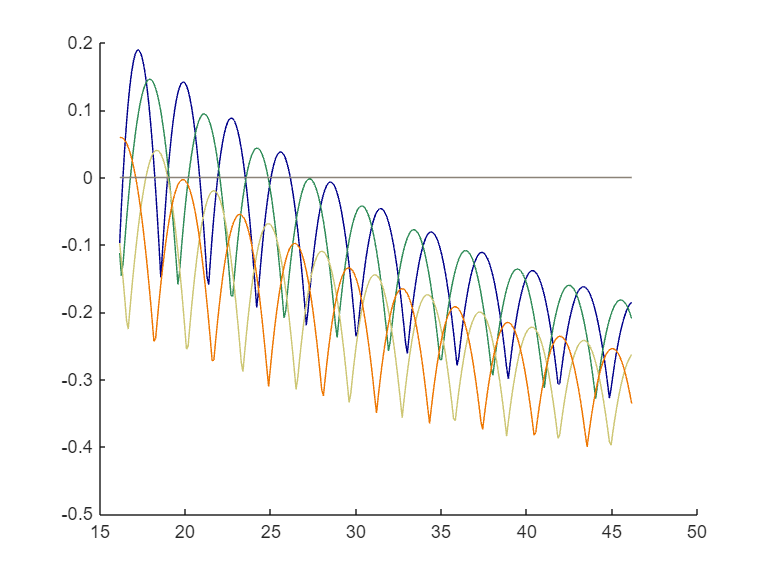

figure
hold on
 plot(theta_show_q1(:,1),all_(:,1),'color',[0 0 139]/255)
 plot(theta_show_q1(:,1),all_(:,2),'color',[46 139 87]/255)
 plot(theta_show_q1(:,1),all_(:,3),'color',[205 198 115]/255)
 plot(theta_show_q1(:,1),all_(:,4),'color',[238 118 0]/255)
plot(theta_show_q1(:,1), zeros(size(theta_show_q1(:,1))),'color',[139 131 120]/255)

% 封装碰撞判断
function max_err = getmax_single(theta_0,l_h,l,d,N)
    all_thetas = solveAfterPoint(theta_0,d,N+1,l,l_h);
    max_err = max(crossfunctions(all_thetas(1), all_thetas(2:end),...
        d * all_thetas(1)/2/pi, ...
        d * all_thetas(2:end)/2/pi, N, l_h, l),[],"all");
end

% function max_err = getmax_par(theta_0,l_h,l,d,N)
%     all_thetas = solveAfterPoint(theta_0,d,N+1,l,l_h);
%     max_err = max(crossfunctions(all_thetas(1), all_thetas(2:end),...
%         d * all_thetas(1)/2/pi, ...
%         d * all_thetas(2:end)/2/pi, N, l_h, l),[],"all");
% end

getmax_single(32*pi,2.86,1.65,0.55,30)

ans = -3.3001

 % solveAfterPoint(32*pi,0.55,223,1.65,2.86)
 % 绘制碰撞判断图像
low = 24;
up = 28;
NN =50;
thetas_sries = zeros(NN,1);
for i =1:NN
    theta_t = low + (up-low)*i/NN;
    thetas_sries(i) = theta_t;
    %maxs(i) = getmax(theta_t,l_h,l,0.55,222);
end

all_theta=solveAfterPoint(thetas_sries,0.55,223,l,l_h);
max_err=NaN(NN,1);
parfor i = 1:NN
    check=crossfunctions(all_theta(i,1), all_theta(i,2:end),...
        d_q1 * all_theta(i,1)/2/pi, ...
        d_q1 * all_theta(i, 2:end)/2/pi, 222, l_h, l);
        max_err(i) = max(check,[],"all");
end

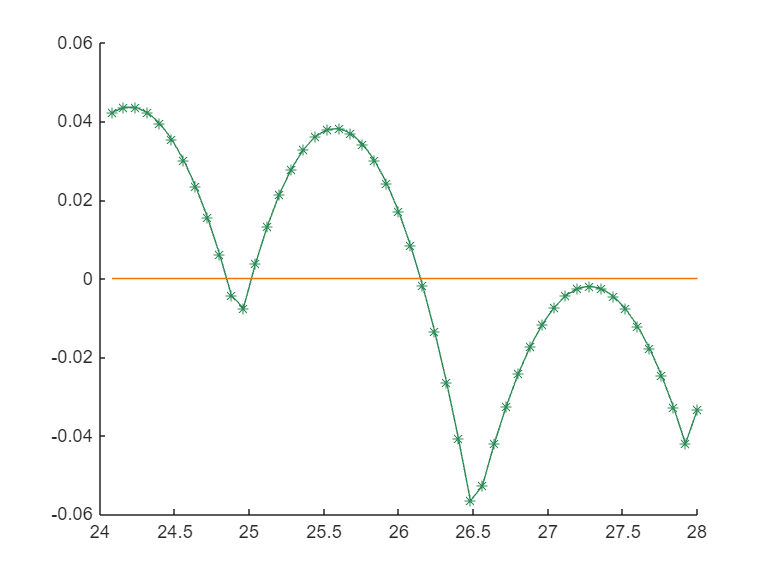

figure
hold on
plot(thetas_sries, max_err,"marker","*", 'Color',[46 139 87]/255)
plot(thetas_sries, zeros(size(thetas_sries)), 'Color',[238 118 0]/255)
hold off


x0 = 26.4; % 初始猜测1
x1 = 26.0; % 初始猜测2
tol = 1e-7; % 容差
max_iter = 300; % 最大迭代次数
for i = 1:max_iter
    f_x0 = getmax_single(x0,l_h,l,d_q1,223);
    f_x1 = getmax_single(x1,l_h,l,d_q1,223);
    x2 = x1 - f_x1 * (x1 - x0) / (f_x1 - f_x0);
    if abs(x2 - x1) < tol
        break;
    end
    x0 = x1;
    x1 = x2;
end
theta_at_edge = x2;

getmax_single(theta_at_edge,l_h,l,d_q1,223)

q2_all_thetas = solveAfterPoint(theta_at_edge,d_q1,223,l,l_h);

% 计算速度
dthetadt_val_q2 = subs(dthetadt_sprial,[d,v],[d_q1,v_q1])
dthetadt_func_q2 = matlabFunction(dthetadt_val_q2, 'Vars', theta_0);

dtheta_idtheta_ip1_val_q2 = zeros(1,223);
parfor i = 1:223
    dtheta_idtheta_ip1_val_q2(1,i) =...
        dtheta_ip1dtheta_i_func(q2_all_thetas(1,i), ...
        q2_all_thetas(1,i+1));

end
dtheta_idtheta_ip1_val_multiplicative_q2 = dtheta_idtheta_ip1_val_q2;
for i = 2:223
    dtheta_idtheta_ip1_val_multiplicative_q2(1,i) =...
    dtheta_idtheta_ip1_val_multiplicative_q2(1,i)...
    *dtheta_idtheta_ip1_val_multiplicative_q2(1,i-1);
end

% 计算速度
vs2 = zeros(1,223);
parfor i = 1:223
    vs2(1,i)=...
    dLdtheta_func(q2_all_thetas(1,i), d_q1)...
    *dtheta_idtheta_ip1_val_multiplicative_q2(1,i)...
    *dthetadt_func_q2(q2_all_thetas(1));
end

vs2=abs(vs2)

t_at_edge = t_theta_0_func_q1(theta_at_edge)

% 第三问
% 求临界极角
syms d
theta0_edge = 9*pi/d

$$theta0\_edge = \frac{9\,\pi }{d}$$

theta0_edge_func = matlabFunction(theta0_edge,"Vars",d);

% 绘制碰撞条件
low = 0.1;
up = 3;
NN3 =50;

d_sries = zeros(NN3+1,1);
thetas_sries3 = zeros(NN3+1,1);
d_sries(1) = low; 
thetas_sries3(1) = theta0_edge_func(low);
for i =1:NN3
    d_t = low + (up-low)*i/NN3;
    d_sries(i+1) = d_t;
    thetas_sries3(i+1) = theta0_edge_func(d_t);

    %maxs(i) = getmax(theta_t,l_h,l,0.55,222);
end

all_theta3=solveAfterPoint(thetas_sries3,d_sries,223,l,l_h);


max_err3=NaN(NN3+1,1);
for i = 1:(NN3+1)
    check=crossfunctions(all_theta3(i,1), all_theta3(i,2:end),...
        d_sries(i) * all_theta3(i,1)/2/pi, ...
        d_sries(i) * all_theta3(i, 2:end)/2/pi, 222, l_h, l);
        max_err3(i) = max(check,[],"all");
end

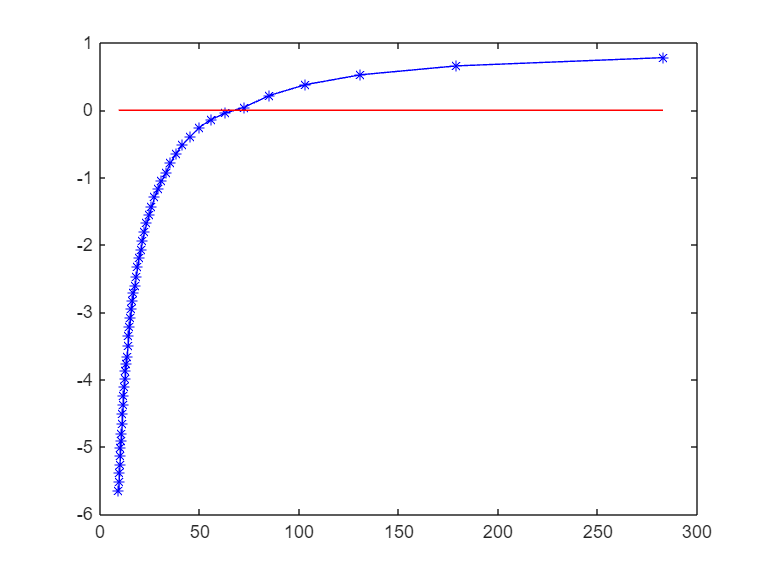

plot(thetas_sries3, max_err3, '-*b', ...
    thetas_sries3, zeros(size(thetas_sries3)), '-r')

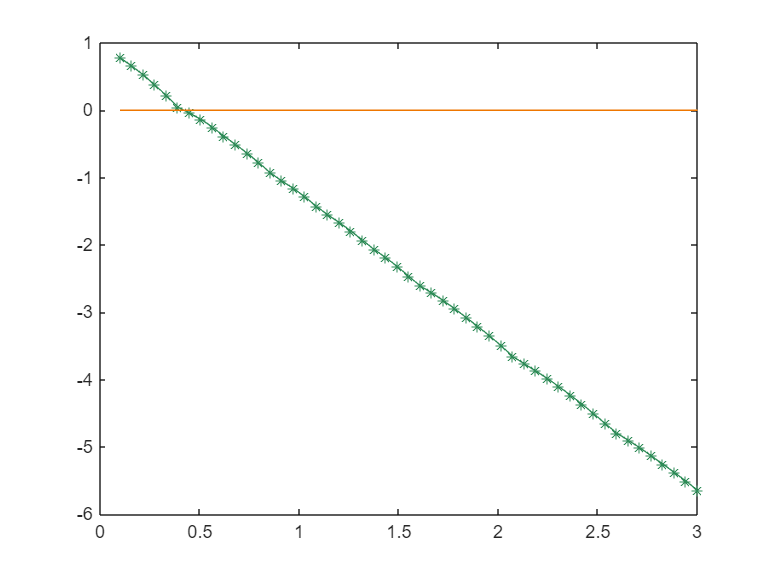

plot(d_sries, max_err3, 'Marker',"*",'Color',[46 139 87]/255)
hold on
plot(d_sries, zeros(size(thetas_sries3)), 'Color',[238 118 0]/255)
hold on

% 割线法搜索
x0 = 0.4; % 初始猜测1
x1 = 0.45; % 初始猜测2
tol = 1e-7; % 容差
max_iter = 300; % 最大迭代次数
for i = 1:max_iter
    disp(i)
    theta_x0 = theta0_edge_func(x0);
    theta_x1 = theta0_edge_func(x1);
    f_x0 = getmax_single(theta_x0,l_h,l,x0,223);
    f_x1 = getmax_single(theta_x1,l_h,l,x1,223);
    x2 = x1 - f_x1 * (x1 - x0) / (f_x1 - f_x0);
    if abs(x2 - x1) < tol
        break;
    end
    x0 = x1;
    x1 = x2;
end
d_at_edge= x2;
theta_at_edge3 = theta0_edge_func(d_at_edge)

getmax_single(theta_at_edge3,l_h,l,d_at_edge,223)

q3_all_thetas = solveAfterPoint(theta_at_edge3,d_at_edge,223,l,l_h);

% 计算速度
dthetadt_val_q3 = subs(dthetadt_sprial,[d,v],[d_at_edge,v_q1])
dthetadt_func_q3 = matlabFunction(dthetadt_val_q3, 'Vars', theta_0);

dtheta_idtheta_ip1_val_q3 = zeros(1,223);
parfor i = 1:223
    dtheta_idtheta_ip1_val_q3(1,i) =...
        dtheta_ip1dtheta_i_func(q3_all_thetas(1,i), ...
        q3_all_thetas(1,i+1));

end
dtheta_idtheta_ip1_val_multiplicative_q3 = dtheta_idtheta_ip1_val_q3;
for i = 2:223
    dtheta_idtheta_ip1_val_multiplicative_q3(1,i) =...
    dtheta_idtheta_ip1_val_multiplicative_q3(1,i)...
    *dtheta_idtheta_ip1_val_multiplicative_q3(1,i-1);
end

% 计算速度
vs3 = zeros(1,223);
parfor i = 1:223
    vs3(1,i)=...
    dLdtheta_func(q3_all_thetas(1,i), d_at_edge)...
    *dtheta_idtheta_ip1_val_multiplicative_q3(1,i)...
    *dthetadt_func_q3(q3_all_thetas(1));
end
vs3=abs(vs3)


% 第四问 

% 确定盘入、盘出掉头区域的的具体参数
R = 4.5;  % 掉头空间的半径
d_q4 = 1.7;  % 螺距
theta_sprial_in = R/d_q4*2*pi;  % 掉头空间边界与盘入螺线交点的极角
theta_change_arc = theta_sprial_in - pi;

h_fun = @(x) (x*cos(x) + sin(x))/(-x*sin(x)+cos(x));
h = h_fun(theta_sprial_in);  % 螺线与圆弧的切线的斜率
atan_h = atan(h);  % 螺线与圆弧的切线的倾斜角(-pi/2, pi/2)
gamma = mod(theta_sprial_in - atan_h - pi/2, pi);  % 螺线与圆弧的切线的法线与进出点连线的夹角
x_sprial_in = R*cos(theta_sprial_in);
y_sprial_in = R*sin(theta_sprial_in);
x_con = -1/3*x_sprial_in;
y_con = -1/3*y_sprial_in;
x_sprial_out = -x_sprial_in;
y_sprial_out = -y_sprial_in;
f11 = @(x) -1/h*(x - x_sprial_in) + y_sprial_in;
f12 = @(x) -1/h*(x - x_sprial_out) + y_sprial_out;
f2 = @(x) tan(atan_h + pi/2 + 2*gamma)*(x - x_con) + y_con;

x_arc_c_in = fzero(@(x) f11(x)-f2(x), 0);  % 第一段弧的圆心
y_arc_c_in = f2(x_arc_c_in);
R_arc_in = norm([x_arc_c_in y_arc_c_in] - [x_sprial_in y_sprial_in]);
r_arc_c_in = norm([x_arc_c_in, y_arc_c_in]);
theta_arc_c_in = atan(y_arc_c_in/x_arc_c_in) + pi;

x_arc_c_out = fzero(@(x) f12(x)-f2(x), 0);  % 第二段弧的圆心
y_arc_c_out = f2(x_arc_c_out);
R_arc_out = norm([x_arc_c_out y_arc_c_out] - [x_sprial_out y_sprial_out]);
r_arc_c_out = norm([x_arc_c_out, y_arc_c_out]);
theta_arc_c_out = atan(y_arc_c_out/x_arc_c_out);

% 求极角反向点
theta_reverse = atan(y_arc_c_out/x_arc_c_out) - asin(R_arc_out/norm([x_arc_c_out, y_arc_c_out]));
k_reverse = tan(theta_reverse);

while theta_reverse + 2*pi < theta_sprial_in
theta_reverse = theta_reverse + 2*pi;
end

theta_sprial_out = 2*theta_reverse - theta_sprial_in+pi;


% 求解不同自然极角下的极径
% 确定各段曲线方程
v_h = 1;
syms theta_real

r_sprial_in = d_q4 /2/pi*theta_real

$$r\_sprial\_in = \frac{1218509242084815\,\theta_{\mathrm{real}}}{4503599627370496}$$

r_sprial_out = d_q4/2/pi*(theta_real+pi)

$$r\_sprial\_out = \frac{1218509242084815\,\theta_{\mathrm{real}}}{4503599627370496}+\frac{1218509242084815\,\pi }{4503599627370496}$$


r_sprial_in_func = matlabFunction(r_sprial_in, 'Vars',theta_real);
r_sprial_out_func = matlabFunction(r_sprial_out, 'Vars',theta_real);

r_arc_in_plus = r_arc_c_in*cos(theta_real-theta_arc_c_in) ...
+ sqrt(r_arc_c_in^2*cos(theta_real-theta_arc_c_in)^2- r_arc_c_in^2+R_arc_in^2);
r_arc_in_minus = r_arc_c_in*cos(theta_real-theta_arc_c_in) ...
- sqrt(r_arc_c_in^2*cos(theta_real-theta_arc_c_in)^2- r_arc_c_in^2+R_arc_in^2); 
r_arc_out_plus = r_arc_c_out*cos(theta_real-theta_arc_c_out) ...
+ sqrt(r_arc_c_out^2*cos(theta_real-theta_arc_c_out)^2- r_arc_c_out^2+R_arc_out^2); 
r_arc_out_minus = r_arc_c_out*cos(theta_real-theta_arc_c_out) ...
- sqrt(r_arc_c_out^2*cos(theta_real-theta_arc_c_out)^2- r_arc_c_out^2+R_arc_out^2);

r_arc_in_plus_func = matlabFunction(r_arc_in_plus, 'Vars',theta_real); 
r_arc_in_minus_func = matlabFunction(r_arc_in_minus, 'Vars',theta_real); 
r_arc_out_plus_func = matlabFunction(r_arc_out_plus, 'Vars',theta_real); 
r_arc_out_minus_func = matlabFunction(r_arc_out_minus, 'Vars',theta_real); 

% 打包成从自然极角得到极径的函数
r_from_theta_natual = CombinedFunction();
r_from_theta_natual=r_from_theta_natual.setFunction(r_sprial_in_func, r_sprial_out_func, ...
    r_arc_in_plus_func, r_arc_out_minus_func, r_arc_out_plus_func);
r_from_theta_natual=r_from_theta_natual.setThreshold(theta_sprial_in, theta_sprial_out, theta_reverse,theta_change_arc);

getr = @(theta_n) r_from_theta_natual.evaluate(theta_n);

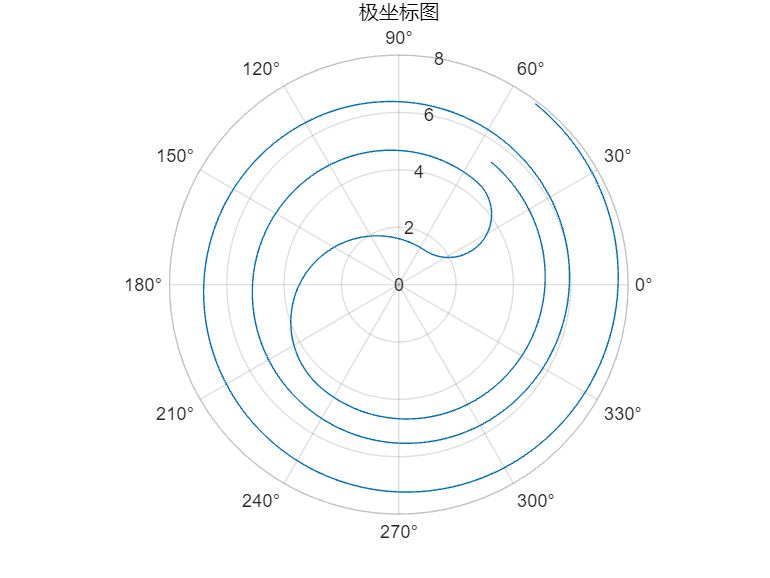

figure
% 定义极角 theta
%theta_plot_n = linspace(-4*pi, 4*pi, 1000);
theta_plot_n = linspace(theta_sprial_out-4*pi, theta_sprial_in+pi, 5000);
%theta_plot_n = linspace(theta_reverse, theta_sprial_in+pi, 5000);
%theta_plot_n = linspace(theta_sprial_out+pi, theta_reverse-0.001, 5000);

% 定义极径 r，假设 getr 是一个函数句柄
r_plot = arrayfun(getr,theta_plot_n);
theta_plot_r = r_from_theta_natual.getRealTheta(theta_plot_n);

% 绘制极坐标图
polarplot(theta_plot_r, r_plot);
title('极坐标图');

% 求解不同自然极角下的弧线长度对真实极角的导数
% 求解不同自然极角下弧线长度对真实极角的导数
syms theta_real

dLdtheta_r_sprial_in = - simplify(sqrt((r_sprial_in)^2+diff(r_sprial_in,theta_real)^2));
dLdtheta_r_sprial_out = simplify(sqrt((r_sprial_out)^2+diff(r_sprial_out,theta_real)^2));
dLdtheta_r_arc_in_plus = - simplify(sqrt((r_arc_in_plus)^2+diff(r_arc_in_plus,theta_real)^2));
dLdtheta_r_arc_out_minus = - simplify(sqrt((r_arc_out_minus)^2+diff(r_arc_out_minus,theta_real)^2));
dLdtheta_r_arc_out_plus = simplify(sqrt((r_arc_out_plus)^2+diff(r_arc_out_plus,theta_real)^2));
% 求解不同自然极角下弧线长度对自然极角的导数
dLdtheta_n_sprial_in =  dLdtheta_r_sprial_in;
% dLdtheta_n_sprial_out = - subs(dLdtheta_r_sprial_out,theta_real,2*theta_reverse - theta_real);
dLdtheta_n_sprial_out = - dLdtheta_r_sprial_out;
dLdtheta_n_arc_in_plus = dLdtheta_r_arc_in_plus;
dLdtheta_n_arc_out_minus = dLdtheta_r_arc_out_minus;
% dLdtheta_n_arc_out_plus = - subs(dLdtheta_r_arc_out_plus,theta_real,2*theta_reverse - theta_real);
dLdtheta_n_arc_out_plus = - dLdtheta_r_arc_out_plus;
% 转化为函数对象
dLdtheta_n_sprial_in_func = matlabFunction(dLdtheta_n_sprial_in, 'Vars', theta_real);
dLdtheta_n_sprial_out_func = matlabFunction(dLdtheta_n_sprial_out, 'Vars', theta_real);
dLdtheta_n_arc_in_plus_func = matlabFunction(dLdtheta_n_arc_in_plus, 'Vars', theta_real);
dLdtheta_n_arc_out_minus_func = matlabFunction(dLdtheta_n_arc_out_minus, 'Vars', theta_real);
dLdtheta_n_arc_out_plus_func = matlabFunction(dLdtheta_n_arc_out_plus, 'Vars', theta_real);
% 打包成从自然极角得到弧线长度对自然极角的导数的函数
dLdtheta_n_from_theta_natual = CombinedFunction();
dLdtheta_n_from_theta_natual=dLdtheta_n_from_theta_natual.setFunction(dLdtheta_n_sprial_in_func, dLdtheta_n_sprial_out_func, ...
    dLdtheta_n_arc_in_plus_func, dLdtheta_n_arc_out_minus_func, dLdtheta_n_arc_out_plus_func);
dLdtheta_n_from_theta_natual=dLdtheta_n_from_theta_natual.setThreshold(theta_sprial_in, theta_sprial_out, theta_reverse,theta_change_arc);

getdLdtheta = @(theta_n) dLdtheta_n_from_theta_natual.evaluate(theta_n);

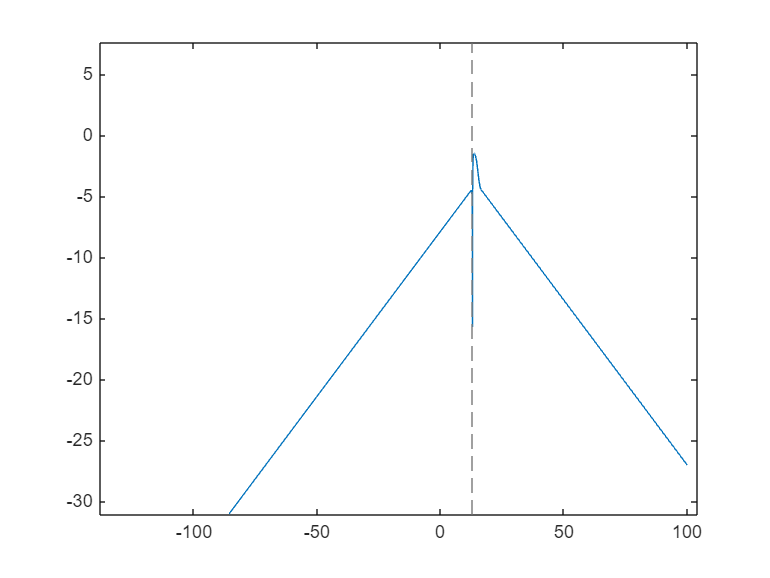

fplot(getdLdtheta, [-100, 100]);

% 对龙头的，不同自然极角下自然极角对时间的导数
dthetandt_sprial_in = simplify(v_h/dLdtheta_n_sprial_in);
dthetandt_sprial_out = simplify(v_h/dLdtheta_n_sprial_out);
dthetandt_arc_in_plus = simplify(v_h/dLdtheta_n_arc_in_plus);
dthetandt_arc_out_minus = simplify(v_h/dLdtheta_n_arc_out_minus);
dthetandt_arc_out_plus = simplify(v_h/dLdtheta_n_arc_out_plus);

dthetandt_sprial_in_func= matlabFunction(dthetandt_sprial_in, 'Vars', theta_real);
dthetandt_sprial_out_func= matlabFunction(dthetandt_sprial_out, 'Vars', theta_real);
dthetandt_arc_in_plus_func= matlabFunction(dthetandt_arc_in_plus , 'Vars', theta_real);
dthetandt_arc_out_minus_func= matlabFunction(dthetandt_arc_out_minus, 'Vars', theta_real);
dthetandt_arc_out_plus_func= matlabFunction(dthetandt_arc_out_plus, 'Vars', theta_real);
% 打包成对龙头的从自然极角得到弧线长度对时间的导数的函数
dthetandt_from_theta_natual = CombinedFunction();

dthetandt_from_theta_natual=dthetandt_from_theta_natual.setFunction(dthetandt_sprial_in_func, dthetandt_sprial_out_func, ...
    dthetandt_arc_in_plus_func, dthetandt_arc_out_minus_func, dthetandt_arc_out_plus_func);

dthetandt_from_theta_natual=dthetandt_from_theta_natual.setThreshold(theta_sprial_in, theta_sprial_out, theta_reverse,theta_change_arc);

getdtheta0ndt = @(theta_n) dthetandt_from_theta_natual.evaluate(theta_n);

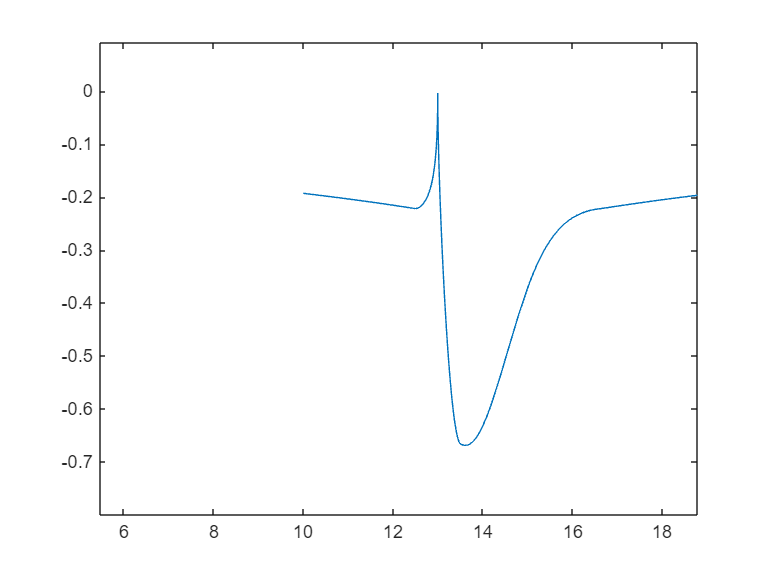

fplot(getdtheta0ndt, [10, 20]);

% 求不同时间下龙头极角的值（数值解）
% 定义微分方程
% dthetadt 就是 getdthetardt
% 设置初始条件和时间范围
theta0_q4 = theta_sprial_in; % 初始条件
tspan_q4_pos = 0:1:100; % 时间范围从 0 到 300

% 调用 ode45 求解
opts = odeset('RelTol',1e-10,'AbsTol',1e-10);
[t_q4_pos, theta_0_val_q4_pos] = ode45(@(t, theta_temp) getdtheta0ndt(theta_temp), tspan_q4_pos, theta0_q4,opts);
% [t, theta_0_val] = ode45(@(t, theta) dthetadt_func(theta), tspan, theta0);

tspan_q4_neg = -100:1:0; % 时间范围从 0 到 300

% 调用 ode45 求解
opts = odeset('RelTol',1e-10,'AbsTol',1e-10);
[t_q4_neg, theta_0_val_q4_neg] = ode45(@(t, theta_temp) getdtheta0ndt(theta_temp), fliplr(tspan_q4_neg), theta0_q4,opts);
% [t, theta_0_val] = ode45(@(t, theta) dthetadt_func(theta), tspan, theta0);
% 绘制结果
theta_0_val_q4_neg = fliplr(theta_0_val_q4_neg);
t_q4 =[t_q4_neg,t_q4_pos];
theta_0_val_q4_show = [theta_0_val_q4_neg,theta_0_val_q4_pos];
plot(t_q4, theta_0_val_q4_show);
xlabel('时间 t');
ylabel('解 \theta(t)');
theta_0_val_q4=[flipud(theta_0_val_q4_neg);theta_0_val_q4_pos(2:end)];


% thetas_val_q1  = theta_0_val_q1
%thetas_val_q1 = addNextPoint(thetas_val_q1,l_h,d_q1)
% 计算不同时刻下龙头后各点的极角 theta_0,howManyPointsAfterHead,l,l_h,curve
thetas_val_q4_all = solveAfterPoint_arbitrary(theta_0_val_q4,223,l,l_h,getr);
thetas_val_q4 = thetas_val_q4_all(:,2:end);

% 计算速度
% 首先分别讨论dtheta_i+1/dtheta_i 在不同情况下的函数 符号对象
syms theta_ip1 theta_i

getdd = @(r_ip1_,r_i_,theta_ip1_,theta_i_) -diff(r_ip1_^2+r_i_^2-2*r_ip1_*r_i_*cos(theta_ip1_-theta_i_),theta_i_)...
/diff(r_ip1_^2+r_i_^2-2*r_ip1_*r_i_*cos(theta_ip1_-theta_i_),theta_ip1_);
dd_s_in_s_in = simplify(getdd(subs(r_sprial_in,theta_real,theta_ip1),subs(r_sprial_in,theta_real,theta_i),theta_ip1,theta_i));
dd_s_in_a_in = simplify(getdd(subs(r_sprial_in,theta_real,theta_ip1),subs(r_arc_in_plus,theta_real,theta_i),theta_ip1,theta_i));
dd_a_in_a_in = simplify(getdd(subs(r_arc_in_plus,theta_real,theta_ip1),subs(r_arc_in_plus,theta_real,theta_i),theta_ip1,theta_i));
dd_a_in_a_o1 = simplify(getdd(subs(r_arc_in_plus,theta_real,theta_ip1),subs(r_arc_out_minus,theta_real,theta_i),theta_ip1,theta_i));
dd_a_in_a_o2 = simplify(getdd(subs(r_arc_in_plus,theta_real,theta_ip1),subs(r_arc_out_plus,theta_real,theta_i),theta_ip1,theta_i));
dd_a_o1_a_o1 = simplify(getdd(subs(r_arc_out_minus,theta_real,theta_ip1),subs(r_arc_out_minus,theta_real,theta_i),theta_ip1,theta_i));
dd_a_o1_a_o2 = simplify(getdd(subs(r_arc_out_minus,theta_real,theta_ip1),subs(r_arc_out_plus,theta_real,theta_i),theta_ip1,theta_i));
dd_a_o1_s_ou = simplify(getdd(subs(r_arc_out_minus,theta_real,theta_ip1),subs(r_sprial_out,theta_real,theta_i),theta_ip1,theta_i));
dd_a_o2_a_o2 = simplify(getdd(subs(r_arc_out_plus,theta_real,theta_ip1),subs(r_arc_out_plus,theta_real,theta_i),theta_ip1,theta_i));
dd_a_o2_s_ou = simplify(getdd(subs(r_arc_out_plus,theta_real,theta_ip1),subs(r_sprial_out,theta_real,theta_i),theta_ip1,theta_i));
dd_s_ou_s_ou = simplify(getdd(subs(r_sprial_out,theta_real,theta_ip1),subs(r_sprial_out,theta_real,theta_i),theta_ip1,theta_i));


% 转为函数对象
dd_s_in_s_in_func = matlabFunction(dd_s_in_s_in,'Vars',[theta_ip1,theta_i]);
dd_s_in_a_in_func = matlabFunction(dd_s_in_a_in,'Vars',[theta_ip1,theta_i]);
dd_a_in_a_in_func = matlabFunction(dd_a_in_a_in,'Vars',[theta_ip1,theta_i]);
dd_a_in_a_o1_func = matlabFunction(dd_a_in_a_o1,'Vars',[theta_ip1,theta_i]);
dd_a_in_a_o2_func = matlabFunction(dd_a_in_a_o2,'Vars',[theta_ip1,theta_i]);
dd_a_o1_a_o1_func = matlabFunction(dd_a_o1_a_o1,'Vars',[theta_ip1,theta_i]);
dd_a_o1_a_o2_func = matlabFunction(dd_a_o1_a_o2,'Vars',[theta_ip1,theta_i]);
dd_a_o1_s_ou_func = matlabFunction(dd_a_o1_s_ou,'Vars',[theta_ip1,theta_i]);
dd_a_o2_a_o2_func = matlabFunction(dd_a_o2_a_o2,'Vars',[theta_ip1,theta_i]);
dd_a_o2_s_ou_func = matlabFunction(dd_a_o2_s_ou,'Vars',[theta_ip1,theta_i]);
dd_s_ou_s_ou_func = matlabFunction(dd_s_ou_s_ou,'Vars',[theta_ip1,theta_i]);

% 打包成类对象
dd_ip1_i = Combinedd();
dd_ip1_i = dd_ip1_i.setFunction( ...
    dd_s_in_s_in_func,...
    dd_s_in_a_in_func,...
    dd_a_in_a_in_func,...
    dd_a_in_a_o1_func,...
    dd_a_in_a_o2_func,...
    dd_a_o1_a_o1_func,...
    dd_a_o1_a_o2_func,...
    dd_a_o1_s_ou_func,...
    dd_a_o2_a_o2_func,...
    dd_a_o2_s_ou_func,...
    dd_s_ou_s_ou_func);
dd_ip1_i = dd_ip1_i.setThreshold(theta_sprial_in, theta_sprial_out, theta_reverse,theta_change_arc);
get_dtheta_ip1_dtheta_i =@(t_ip1,t_i) dd_ip1_i.evaluate(t_ip1,t_i);

    % 计算速度
function vs=getvs_q4(thetas_val_all, dthetaip1_dthetai,dtheta0ndt,dLdtheta)

    [n,nn] =size(thetas_val_all);
    nn = nn-1;
    dtheta_idtheta_ip1_valq4 = zeros(n,nn);
    for i = 1:nn
        for j = 1:n
            dtheta_idtheta_ip1_valq4(j,i) = dthetaip1_dthetai(thetas_val_all(j,i+1),thetas_val_all(j,i));
        end
    end
    dtheta_idtheta_ip1_val_multiplicative4 = dtheta_idtheta_ip1_valq4;
    for i = 2:nn
        for j = 1:n
            dtheta_idtheta_ip1_val_multiplicative4(j,i) = ...
            dtheta_idtheta_ip1_val_multiplicative4(j,i)*dtheta_idtheta_ip1_val_multiplicative4(j,i-1);
        end
    end

    vs_ = zeros(n,nn);
    for i = 1:nn
        for j = 1:n
            vs_(j,i)=dtheta0ndt(thetas_val_all(j,1))*dtheta_idtheta_ip1_val_multiplicative4(j,i)*dLdtheta(thetas_val_all(j,i+1));
        end
    end
    vs = abs(vs_);
end
%  增加一层封装，只返回最大值速度和其索引
function [vmax, index] = getvsmax_q5(thetas_val_all, dthetaip1_dthetai, dtheta0ndt, dLdtheta)
    % 计算 vs 矩阵
    vs = getvs_q4(thetas_val_all, dthetaip1_dthetai, dtheta0ndt, dLdtheta);
    
    % 找到 vs 矩阵中的最大值及其线性索引
    [vmax, index] = max(vs,[],2);
    
    % 将线性索引转换为行列索引
    % [row, col] = ind2sub(size(vs), linearIndex);
end

vs_q4 = getvs_q4(thetas_val_q4_all,get_dtheta_ip1_dtheta_i,getdtheta0ndt,getdLdtheta);

close all;

function no=drow(thetas,rfromthetas,real_theta_from_theta)
    rho = arrayfun(rfromthetas,thetas);
    thetas_val_all_plot = real_theta_from_theta(thetas);
    max_r = max(rho,[],"all");

% 遍历每一行并绘制极坐标散点图
    for i = 1:size(thetas_val_all_plot, 1)
        % 绘制第一个点
        % rlim([0 max_r]);
        polarplot(thetas_val_all_plot(i,1), rho(i,1), 'ro','MarkerSize',3, 'MarkerFaceColor', 'r'); % 红色实心点
        hold on;

        % 绘制其余的点
        polarplot(thetas_val_all_plot(i,2:end), rho(i,2:end), 'bo','MarkerSize',3); % 蓝色点

        % 绘制连线
        polarplot(thetas_val_all_plot(i,:)', rho(i,:)', '-',"Color",[139 131 120]/255); % 绿色线
        %polarscatter(thetas_val_all_plot(i, :), rho(i, :),25,c,'filled');
        hold off
         pause(0.05);

    end
    no=1;
end

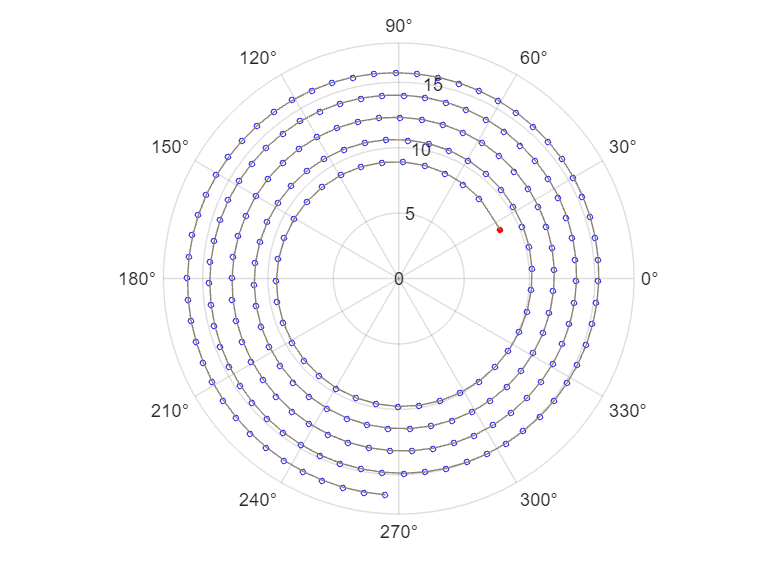

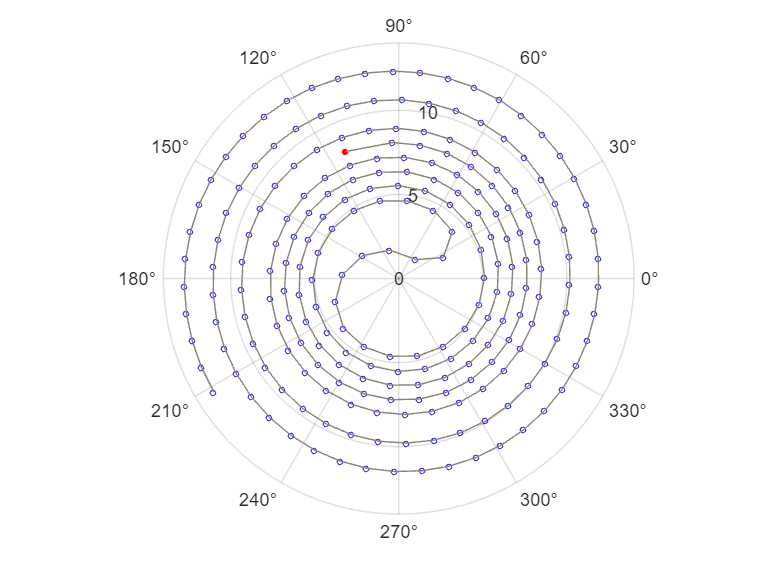

ans = 1

figure
drow(thetas_val_q4_all,getr,@(t_n) r_from_theta_natual.getRealTheta(t_n))

[maxv,maxindex]=max(vs_q4,[],2)

% 第五问
% 利用第四问的结果，在龙头把手速度取1时计算各节点在不同位置时的速度，取其最大值并调整龙头速度令其等于2m/s
% 龙头把手位置搜索范围的确定
theta0_searching_range = linspace(theta_sprial_in + pi, -27, 1000)';
theras_all_searching = solveAfterPoint_arbitrary(theta0_searching_range,223,l,l_h,getr);
v_max_infor = zeros(length(theta0_searching_range),2);
axv_and_theta_and_theta0_and_index=zeros(length(theta0_searching_range),4);


drow(theras_all_searching ,getr,@(t_n) r_from_theta_natual.getRealTheta(t_n))

goal = get_goal_func;goal = goal.setFunction(@(x) solveAfterPoint_arbitrary(x,223,l,l_h,getr), ...
    @(x) getvs_q4(x,get_dtheta_ip1_dtheta_i,getdtheta0ndt,getdLdtheta));
maxtheta = @(theta) -goal.evaluate(theta);
x0 = 12.3291142;

% 调用模拟退火算法
[x, fval] = fminsearch(maxtheta, x0);

% 显示结果
disp(['最优解: ', num2str(x)]);
disp(['目标函数值: ', num2str(fval)]);

2/fval

ans = -1.2446

vs_q5 = getvs_q4(theras_all_searching,get_dtheta_ip1_dtheta_i,getdtheta0ndt,getdLdtheta);


[maxVsee,maxIndexsee] = max(vs_q5,[],2);
plot(theta0_searching_range,maxVsee)

goal = get_goal_func;goal = goal.setFunction(@(x) solveAfterPoint_arbitrary(x,223,l,l_h,getr), ...
    @(x) getvs_q4(x,get_dtheta_ip1_dtheta_i,getdtheta0ndt,getdLdtheta));
maxtheta = @(theta) goal.evaluate(theta);
x0 = 0;

% 调用模拟退火算法
[x, fval] = simulannealbnd(fun, x0);

% 显示结果
disp(['最优解: ', num2str(x)]);
disp(['目标函数值: ', num2str(fval)]);